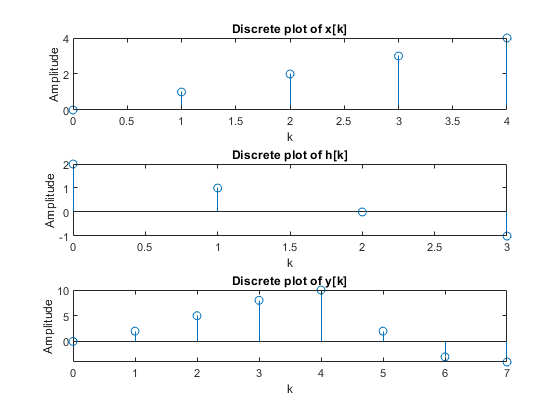


x = (0:4);
k = (0:length(x)-1);


figure('Name', 'Convolution')
subplot(3, 1, 1)
stem(k,x)
title('Discrete plot of x[k]')
xlabel('k')
ylabel('Amplitude')
subplot(3, 1, 2)

h = (2:-1:-1);
k1 = (0:length(h)-1);
stem(k1,h)
title('Discrete plot of h[k]')
xlabel('k')
ylabel('Amplitude')

y = conv(x,h);
k2 = (0:length(y)-1);
subplot(3, 1, 3)
stem(k2,y)
title('Discrete plot of y[k]')
xlabel('k')
ylabel('Amplitude')

clear
k = (0:50)

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


h = 0.3*sinc(0.3.*(k-25)).*(0.54-0.46*cos(2*pi.*k/50))

h =    -0.0010   -0.0007    0.0004    0.0015    0.0017   -0.0000   -0.0028   -0.0042   -0.0017    0.0040    0.0084    0.0061   -0.0039   -0.0144   -0.0147    0.0000    0.0211    0.0298    0.0117   -0.0273   -0.0581   -0.0441    0.0317    0.1492    0.2566    0.3000    0.2566    0.1492    0.0317   -0.0441   -0.0581   -0.0273    0.0117    0.0298    0.0211    0.0000   -0.0147   -0.0144   -0.0039    0.0061    0.0084    0.0040   -0.0017   -0.0042   -0.0028   -0.0000    0.0017    0.0015    0.0004   -0.0007



[x,Fs]  = audioread("baila.wav");

figure('Name', 'Convolution on wav')
y = conv(h,x);
k1 = (0:length(y)-1)

k1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


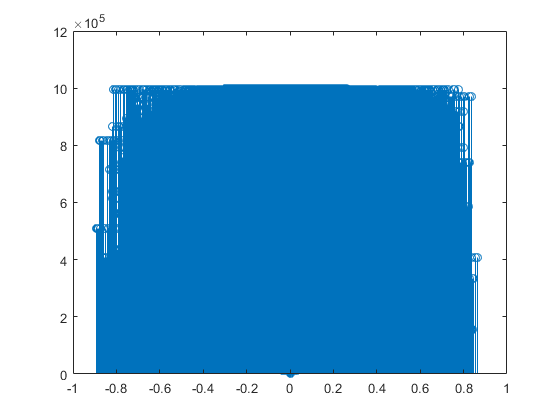

stem (y,k1)


audiowrite('baila_filtered.wav', y, Fs)

clear

%x1 = cos(20*pi.*t)
%x2 = cos(180*pi.*t)
% fz = 100Hz
n1 = (0:30)

n1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


y1 = cos(20*pi.*n1/100)

y1 =     1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000


y2 = cos(180*pi.*n1/100)

y2 =     1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000


y3 = cos(220*pi.*n1/100)

y3 =     1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000    0.8090    0.3090   -0.3090   -0.8090   -1.0000   -0.8090   -0.3090    0.3090    0.8090    1.0000


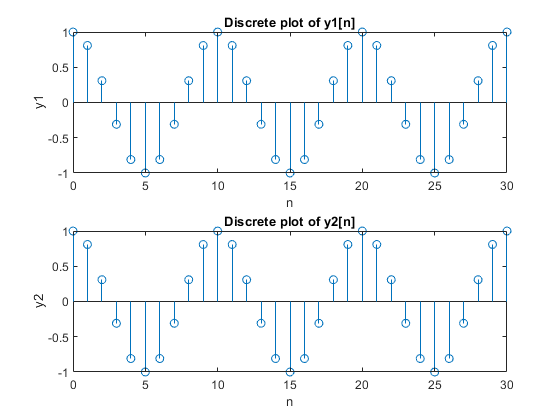



figure('Name', 'Alising with 100Hz')
subplot(2,1,1);
stem(n1, y1)

title('Discrete plot of y1[n]')
xlabel('n')
ylabel('y1')

subplot(2,1,2);
stem(n1, y2)

title('Discrete plot of y2[n]')
xlabel('n')
ylabel('y2')


fs1 = 100

fs1 = 100

fs2 = 1000

fs2 = 1000

n2 = (0:300)

n2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


z1 = cos(20*pi.*n2/1000)

z1 =     1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628    0.0000   -0.0628   -0.1253   -0.1874   -0.2487   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298   -0.9511   -0.9686   -0.9823   -0.9921   -0.9980


z2 = cos(180*pi.*n2/1000)

z2 =     1.0000    0.8443    0.4258   -0.1253   -0.6374   -0.9511   -0.9686   -0.6845   -0.1874    0.3681    0.8090    0.9980    0.8763    0.4818   -0.0628   -0.5878   -0.9298   -0.9823   -0.7290   -0.2487    0.3090    0.7705    0.9921    0.9048    0.5358    0.0000   -0.5358   -0.9048   -0.9921   -0.7705   -0.3090    0.2487    0.7290    0.9823    0.9298    0.5878    0.0628   -0.4818   -0.8763   -0.9980   -0.8090   -0.3681    0.1874    0.6845    0.9686    0.9511    0.6374    0.1253   -0.4258   -0.8443


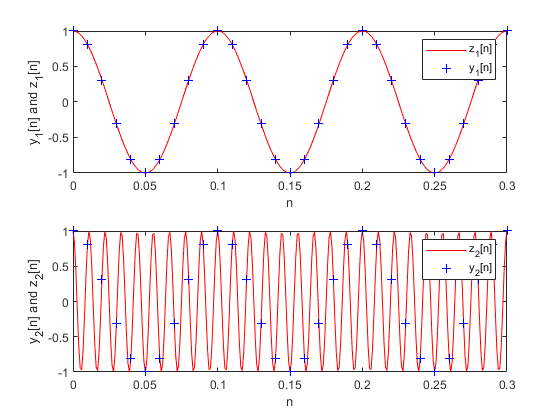




figure('Name', 'Alising compare')
subplot(2,1,1);
plot(n2/fs2,z1,'r-', n1/fs1,y1,'b+'); 
xlabel('n'); ylabel('y_1[n] and z_1[n]'); 
legend('z_1[n]','y_1[n]');
subplot(2,1,2);
plot(n2/fs2,z2,'r-', n1/fs1,y2,'b+');
xlabel('n'); 
ylabel('y_2[n] and z_2[n]'); 
plot(n2/fs2,z2,'r-', n1/fs1,y2,'b+');
xlabel('n'); ylabel('y_1[n] and z_1[n]'); 
legend('z_1[n]','y_1[n]');
subplot(2,1,2);
plot(n2/fs2,z2,'r-', n1/fs1,y2,'b+');
xlabel('n'); ylabel('y_2[n] and z_2[n]'); 
legend('z_2[n]','y_2[n]');

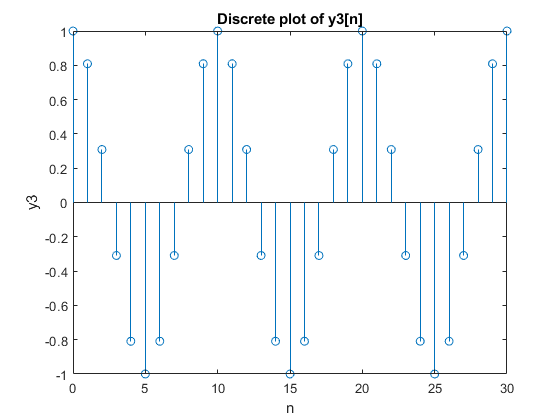




figure('Name', 'Alising with 100Hz with another graph')
stem(n1, y3)

title('Discrete plot of y3[n]')
xlabel('n')
ylabel('y3')

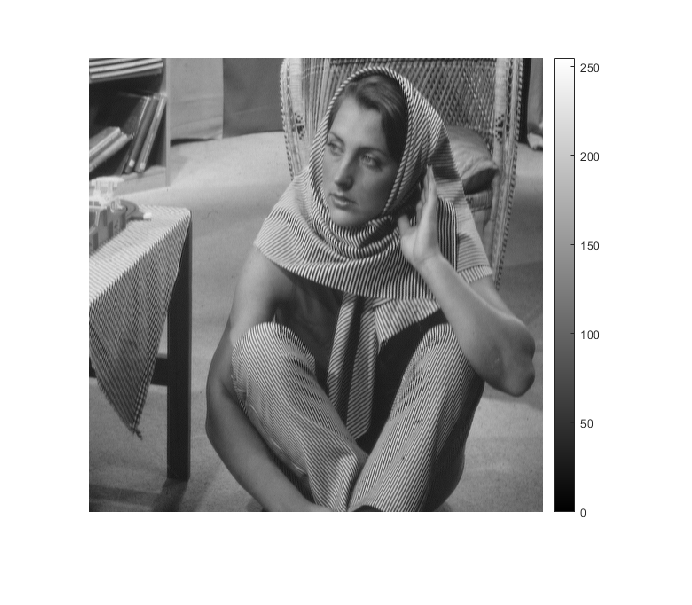

img = imread("barbaraLarge.jpg");



imshow(img), colorbar;

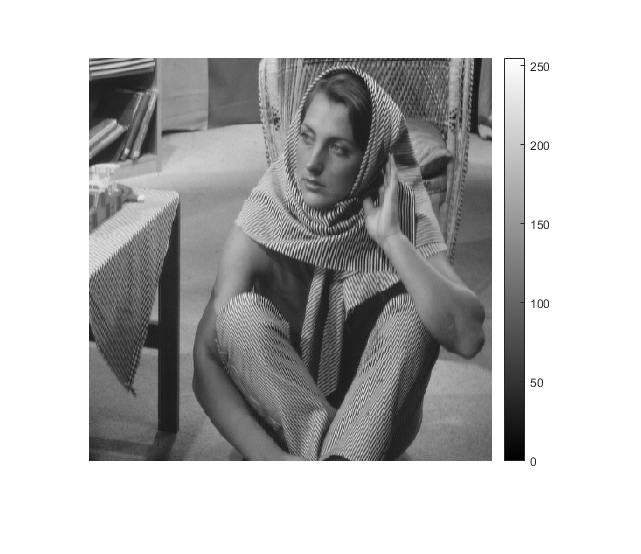


a = imresize(img, 0.9, 'nearest', 'antialiasing', 1);
imshow(a), colorbar;

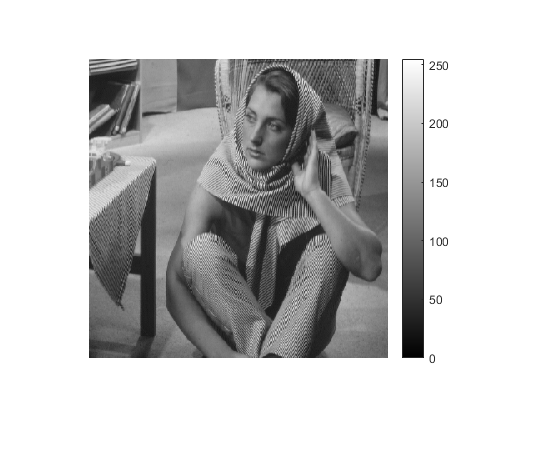


b = imresize(img, 0.7, 'nearest', 'antialiasing', 1);
imshow(b), colorbar;


c = imresize(img, 0.9, 'nearest', 'antialiasing', 1);
imshow(c), colorbar;

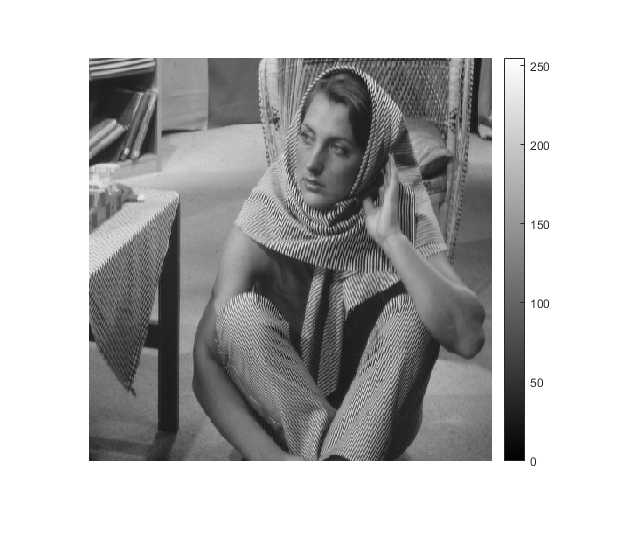



a1 = imresize(img, 0.9, 'nearest', 'antialiasing', 0);
imshow(a1), colorbar;

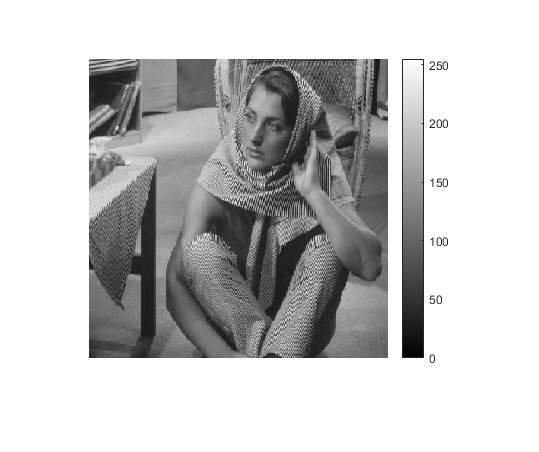


b1 = imresize(img, 0.7, 'nearest', 'antialiasing', 0);
imshow(b1), colorbar;


c1 = imresize(img, 0.9, 'nearest', 'antialiasing', 0);
imshow(c1), colorbar;



%imwrite(lena_bright, 'lena_bright.jpg', 'jpg', 'Quality', 100)